### **Study of Simple Pendulum using MATLAB**

syms m a g theta(t);
eqn = m*a == -1*m*g*sin(theta);

Substitute for a by using subs

syms r;
eqn = subs(eqn,a,r*diff(theta,2));

Isolate the angular acceleration in eqn by using isolate

eqn=isolate(eqn,diff(theta,2));

collect constants g and r into a single parameter,called the natural frequency

syms omega_0;
eqn=subs(eqn,g/r,omega_0^2);

This eqn is difficult to solve analytically because it non-linear.

Asssuming angles are small,we can Linearize the eqn by using the Taylor expansion of sin(theta).

syms x;
approx =taylor(sin(x),x,'Order',2);
approx=subs(approx,x,theta(t));

The Eqn of motion becomes

eqnLinear=subs(eqn,sin(theta(t)),approx);

Solve Eqn of Motion Analytically

syms theta_0 theta_t0;
theta_t=diff(theta);
cond=[theta(0)==theta_0,theta_t(0)==theta_t0];
thetaSol(t)=dsolve(eqnLinear,cond);

Assume omega_0 is real

assume(omega_0,'real');
thetaSol(t) = dsolve(eqnLinear,cond);

Plot Pendulum Motion

Define physical parameters

gValue = 9.81;    % m/s^2
rValue = 1;   % m
omega_0Value = sqrt(gValue/rValue);
t_0 = 2*pi/omega_0Value;

Set initial conditions

theta_0Value=0.1*pi;    % Solution only valid for small angles.
theta_t0Value=0;    % Initaly at rest.

Substitute physical parameters and initial conditions.

vars = [omega_0 theta_0 theta_t0];
values = [omega_0Value theta_0Value theta_t0Value];
thetaSolPlot = subs(thetaSol,vars,values);

Plot for only one cycle.

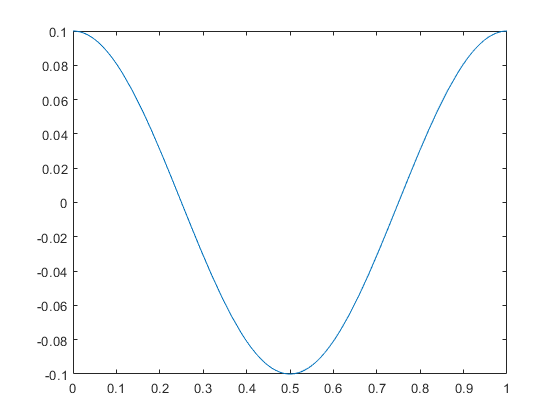

figure;
fplot(thetaSolPlot(t*t_0)/pi,[0,1]);

Plot for repititive cycle

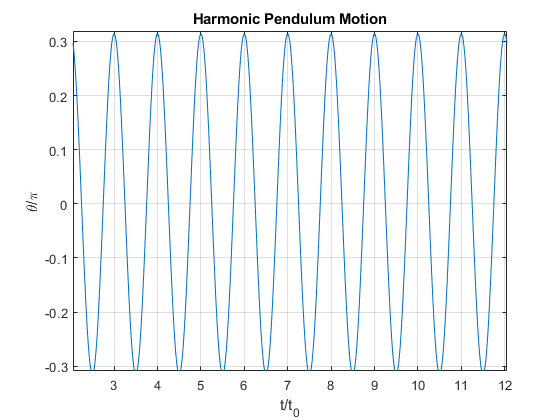

fplot(thetaSolPlot(t*t_0));
grid on;
title('Harmonic Pendulum Motion');
xlabel('t/t_0');
ylabel('\theta/\pi');